## Analysis Pipeline for PEP WP-4 fMRI Project

% house keeping
clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))

### Define to-be-analyzed subjects

cfg.subNums = [101:105, 107:114]; 
cfg = defaultCfg(cfg);


### Define preprocessing and analysis steps

run_all = 0;

if run_all == 1
    create_mcf = 1;
    preproc = 1;
    level1_glm = 1;
    level1_glm_norm = 1;
    level2_glm = 1;
    searchlight_rsa = 1;
    fusion = 1;
else
    % custom pipeline - EDIT ACCORDINGLY!
    create_mcf = 0;
    preproc = 0;
    level1_glm = 0;
    level1_glm_norm = 1;
    level2_glm = 0;
    searchlight_rsa = 0;
    fusion = 0;
end

### Define analysis pipeline

steps = { ...
    'create_mcf', ...
    'preproc', ...
    'level1_glm', ...
    'level1_glm_norm', ...
    'level2_glm', ...
    'searchlight_rsa', ...
    'fusion' ...
    };
flags = [ ...
    create_mcf, ...
    preproc, ...
    level1_glm, ...
    level1_glm_norm, ...
    level2_glm, ...
    searchlight_rsa, ...
    fusion ...
    ];

### Run selected pipeline steps

% for i = 1:length(steps)
%     switch steps{i}
%         case 'preproc'
%             if flags(i) == 1
%                 disp(['Running pre-processing...' newline]);
%                 preproc_func(cfg);
%             end
%         case 'level1_glm'
%             if flags(i) == 1
%                 disp(['Running 1st-level GLM (not normalized)...' newline]);
%                 level1_glm_func(cfg.subNums);
%             end
%         case 'level1_glm_norm'
%             if flags(i) == 1
%                 disp(['Running 1st-level GLM (normalized)...' newline]);
%                 cfg.runwise = true;
%                 level1_glm_norm_func(cfg.subNums, cfg.runwise, cfg.nRuns);
%             end
%         case 'level2_glm'
%             if flags(i) == 1
%                 disp(['Running 2nd-level GLM...' newline]);
%                 glm_func(cfg.subNums, 2);
%             end
%         case 'searchlight_LDA'
%             if flags(i) == 1
%                 disp(['Running searchlight LDA...' newline]);
%                 cfg.map = 't'; % use t cfg.map for decoding
%                 searchlightsLDAclassifier(cfg.subNums, cfg.nRuns, cfg.nTrials, cfg.map)
%             end
%         case 'ROI_LDA'
%             if flags(i) == 1
%                 disp(['Running searchlight LDA...' newline]);
%                 cfg.map = 't'; % use t map for decoding
%                 cfg.rois = {'wV1.nii', 'wV2.nii',...
%                     'wLOC.nii', 'wPPA.nii',...
%                     'wTOS.nii', 'wRSC.nii'};
%                 ROIres = ROIsLDAclassifier(cfg.subNums, cfg.nRuns, cfg.nTrials, cfg.map, cfg.rois);
%             end
%         case 'Pairwise_ROI_LDA'
%             if flags(i) == 1
%                 disp(['Running searchlight LDA...' newline]);
%                 cfg.map = 'b'; % use t map for decoding
%                 cfg.rois = {'wV1.nii', 'wV2.nii',...
%                     'wLOC.nii', 'wPPA.nii',...
%                     'wTOS.nii', 'wRSC.nii'};
%                 PwROIres = PairwisecROIsLDAclassifier(cfg.subNums, cfg.nRuns, cfg.nTrials, cfg.map, cfg.rois);
%             end
%     end
% end

Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
cfg.correlation_type = 'Spearman';

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features')

output_dir = 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\dnn_features'

if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

% get images
images = load_images(cfg);

Loaded image: 001_bat_gen1.png
Loaded image: 001_bat_gen2.png
Loaded image: 001_bat_gen3.png
Loaded image: 002_bat_gen1.png
Loaded image: 002_bat_gen2.png
Loaded image: 002_bat_gen3.png
Loaded image: 003_bat_gen1.png
Loaded image: 003_bat_gen2.png
Loaded image: 003_bat_gen3.png
Loaded image: 004_bat_gen1.png
Loaded image: 004_bat_gen2.png
Loaded image: 004_bat_gen3.png
Loaded image: 005_bat_gen1.png
Loaded image: 005_bat_gen2.png
Loaded image: 005_bat_gen3.png
Loaded image: 007_bat_gen1.png
Loaded image: 007_bat_gen2.png
Loaded image: 007_bat_gen3.png
Loaded image: 008_bat_gen1.png
Loaded image: 008_bat_gen2.png
Loaded image: 008_bat_gen3.png
Loaded image: 009_bat_gen1.png
Loaded image: 009_bat_gen2.png
Loaded image: 009_bat_gen3.png
Loaded image: 010_bat_gen1.png
Loaded image: 010_bat_gen2.png
Loaded image: 010_bat_gen3.png
Loaded image: 011_bat_gen1.png
Loaded image: 011_bat_gen2.png
Loaded image: 011_bat_gen3.png
Loaded image: 012_bat_gen1.png
Loaded image: 012_bat_gen2.png
Loaded i


% typical images
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis typical - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen



% control images
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
analysis control - layer #1 - category: kitchen



% photos
cfg.analysis_name = 'photos';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis photos - layer #1 - category: bathroom
analysis photos - layer #1 - category: kitchen


Get inter-subject similarity on timecourses

% preparation
cfg.plotting = true;
cfg.rois = {'wV1.nii', 'wV2.nii', 'wLOC.nii',...
    'wPPA.nii', 'wTOS.nii', 'wRSC.nii',...
    'wmotorCortex.nii', 'wS1.nii', 'wauditoryCortex.nii'};

% get timecourses (average Voxels for each ROI)
cfg.n_voxels = 5;
funcROIs(cfg)

    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\PPA_funcROI.nii
    Saved functional ROI for TOS to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\TOS_funcROI.nii
    Saved functional ROI for RSC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\RSC_funcROI.nii
    Saved functional ROI for LOC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-001\LOC_funcROI.nii
    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-002\PPA_funcROI.nii
    Saved functional ROI for TOS to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pe

cfg.skipIfExists = false;
cfg.smoothing = true; 
cfg.saveWholeBrain = false;
averageVoxelsInROI(cfg)

Subject: 1
Run: 1
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 2
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 3
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 4
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 5
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 6
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 7
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 8
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 9
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 10
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Subject: 2
Run: 1
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 2
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 3
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 4
Size bathroom: 79  95  79  75
Size kitchen: 79  95  79  75
Run: 5
Size bathroom: 79  95  79  75
Size kitchen: 79


% get ISC from timecourses
cfg.regressOutMean = true;
cfg.correlation_type = 'Pearson';
d = neural_timecourse_intersub_cor(d, cfg);

% get split-half reliability for ISC
d = splithalfReliabilityISC(d, cfg);


d = behResponseISRDM(cfg, d);

Compare ISC from drawings with timecourse ISC

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 bathroom is done
20% of permutations of V1 bathroom is done
30% of permutations of V1 bathroom is done
40% of permutations of V1 bathroom is done
50% of permutations of V1 bathroom is done
60% of permutations of V1 bathroom is done
70% of permutations of V1 bathroom is done
80% of permutations of V1 bathroom is done
90% of permutations of V1 bathroom is done
100% of permutations of V1 bathroom is done
Compare inter-subject RDM of V1 with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 kitchen is done
20% of permutations of V1 kitchen is done
30% of permutations of V1 kitchen is done
40% of permutations of V1 kitchen is done
50% of permutations of V1 kitchen is done
60% of permutations of V1 kitchen is done
70% of permutations of V1 kitchen is done
80% of permutations of V1 kitchen is done
90% of permutations of V1 kitch

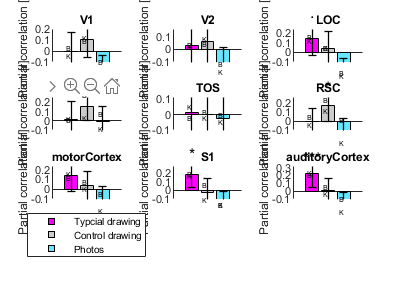

% preparation
cfg.partial_cor = 1;
cfg.plot_rdm = 0;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.rois_of_interest = {'V1', 'V2', 'LOC', 'PPA', ...
    'TOS', 'RSC', 'motorCortex', 'S1', 'auditoryCortex'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = true;
cfg.permutation_test = true;
cfg.bootstrapping = false;
cfg.max_bootstrapping_n = 35;
cfg.n_bootstrapp_iterations = 1000;
cfg.bootstrapp_what = 'runs';
cfg.n_permutations = 100;
cfg.permutation_type = 'row_col_shuffle_pred';
cfg.ISC_type = 'timecourseRDM_concat';
cfg.partial_correlation_type = 'pearson';

d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

Get neural RDMs of single stimuli for each subject

% % preparations
% cfg.rois = {'wV1.nii', 'wV2.nii',...
%     'wLOC.nii', 'wRSC.nii',...
%     'wPPA.nii', 'wTOS.nii',...
%  'wS1.nii', 'wauditoryCortex.nii'};
% cfg.map = 't';
% 
% % run RDM based on simple correlations
% d.simgpleRDMresults = Copy_of_SimpleRDM(cfg.subNums, cfg.nTrials, cfg.map, cfg.rois)

% Get inter-subject similarity on single stimulus RDMs
% % preparation
% cfg.map = 't';
% cfg.plotting = false;
% 
% % run neural ISC script
% [d] = neural_intersub_cor(d, cfg)
% 

Compare ISC from drawings with neural ISC

% % preparation
% cfg.partial_cor = 1;
% cfg.plot_rdm = 0;
% cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late', 'Control Images vgg16_imagenet Late'};
% cfg.predictor_RDMs = {'typical_late', 'control_late'};
% cfg.rois_of_interest = {'wV1', 'wLOC', 'wPPA', ...
%     'wTOS', 'wRSC', 'wmotorCortex', 'wS1', 'wauditoryCortex'};
% cfg.dnns = {'vgg16_imagenet'};
% cfg.plot_type = 'bar';
% cfg.show_single_cate = 1;
% cfg.permutation_test = 1;
% cfg.n_permutations = 1000;
% cfg.permutation_type = 'row_col_shuffle_pred';
% 
% cfg.partial_correlation_type = 'pearson';
% 
% d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

End Message

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);